# CSIRS资源映射

CSIRS（Channel-State Information Reference Signal）是一种在5G通信系统中使用的参考信号。它用于获取基站和用户设备之间的信道状态信息（CSI），以便进行信道估计和反馈。这些信息对于实现多种5G技术和功能非常重要，如波束赋形、干扰消除和自适应调制等，有助于提高5G网络的性能、容量和可靠性，从而满足日益增长的无线通信需求。

CSIRS信令结构如下，可以配置CSIRS参考信号的发送功率偏移、周期和偏移、在slot内的时频域和端口配置等。

**频域RE位置**

对于row1、row2、row4，bit string中置1的数量只能为1，

row1：k0 = [0..3]

row2：k0 = [0..11]

row4：k0 = [0..2]*4

其他row：k0 = [0..5]*2

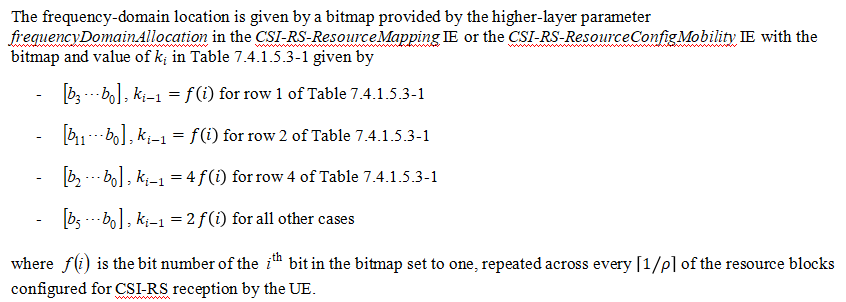

**端口数和码分复用**

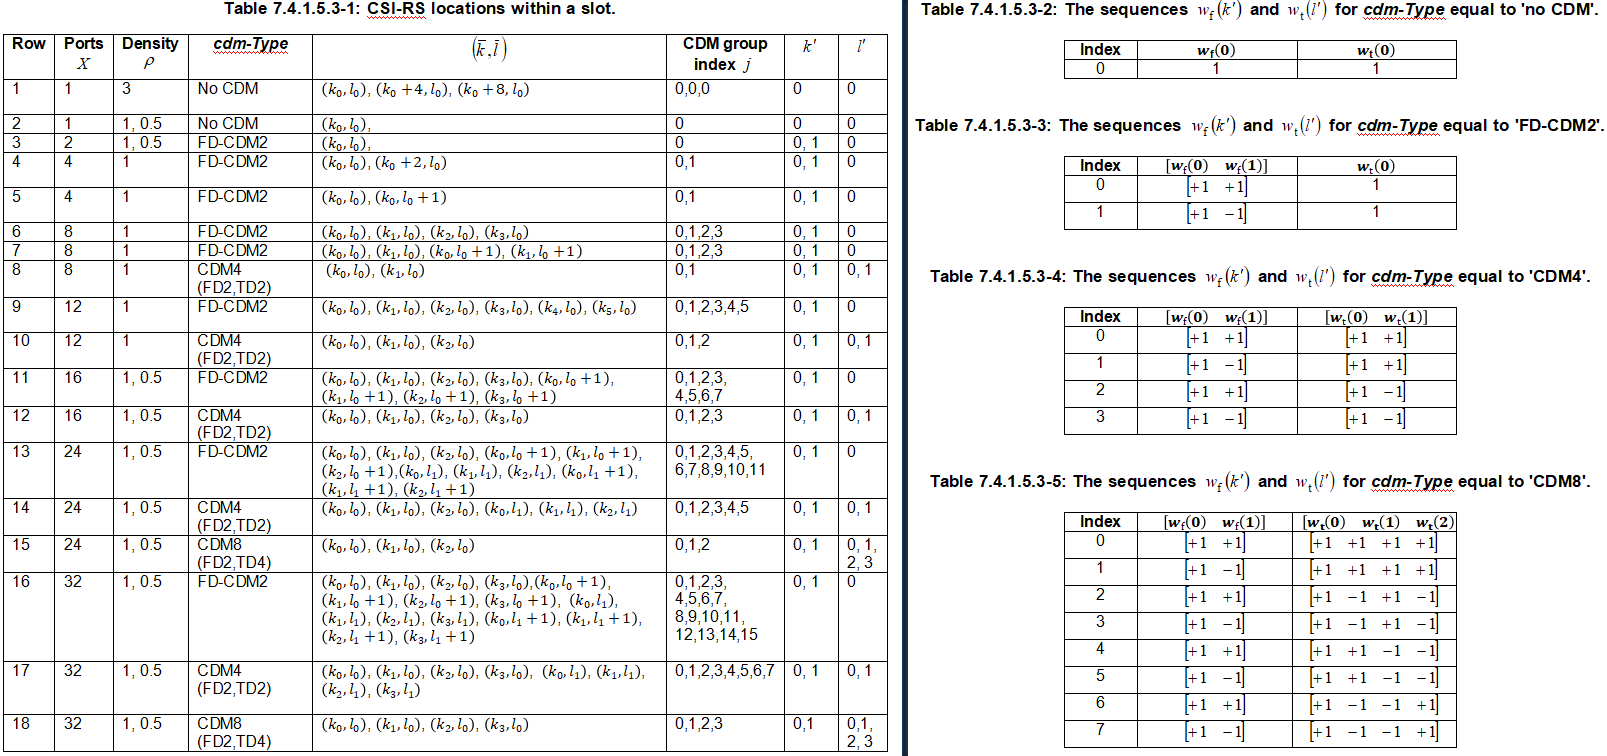

**CDM（Code Division Multiplexing)**

在协议中我们应该知道CSI-RS resource的port数量可以是单个port，也可以是multi-port，最多到32个port。多个CSI-RS port可以在相同时频资源上通过CDM的方式加以区分和映射。

**                                                                                   CSIRS资源的port数 =  频分数 * CDM group num**

在协议中CSI-RS的CDM种类有4种，种类可以根据RRC中的参数cdm-Type得知，{noCDM, fd-CDM2, cdm4-FD2-TD2, cdm8-FD2-TD4}，其中noCDM就是将CSI-RS只映射在一个RE上，没有码分的概念，其余3种如下所示：

FD-CDM2： 在（频域2RE*时域1符号）的2个RE上通过正交码(Orthogonal Cover Code - OCC)实现2个port的复用；

CDM4（FD2，TD2）：在（频域2RE*时域2符号）的4个RE上通过正交码实现4个port的复用；

CDM8（FD2，TD4）：在（频域2RE*时域4符号）的8个RE上通过正交码实现8个port的复用。

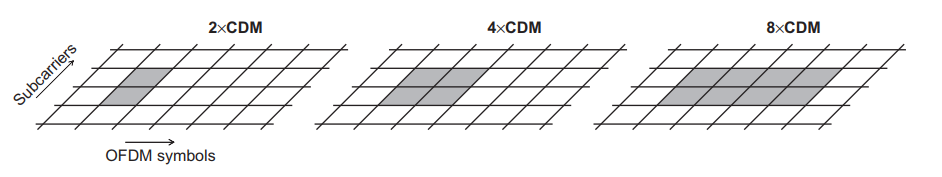

在无线通信系统中，发送端通过在对应端口上发送正交序列。每个端口上的信号在传播过程中会经历不同的信道影响，导致其在接收端表现出不同的变化。为了获得关于信道的信息，通常在发送端采用正交序列的方式，这样接收端可以通过对接收到的信号进行处理，并从码分组内恢复出不同端口上的信道估计。在这个过程中，正交序列的优势在于它们之间相互正交，即在接收端可以很好地分离出不同端口上的信号。因此，接收端可以对接收到的信号进行解调和信号处理，以还原出每个端口上的信道估计。

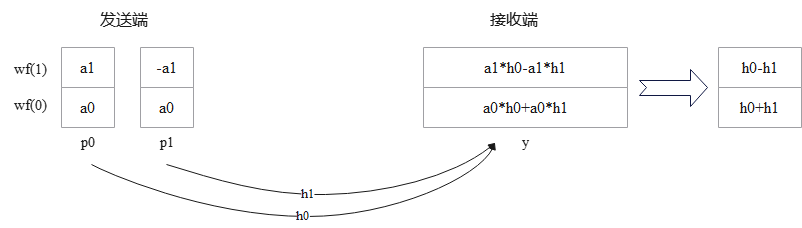

## 1 载波配置

clear;
clc;
close all;

% Carrier configuration
carrier = nrCarrierConfig;
carrier.NCellID = 2;                    % Cell identity
carrier.SubcarrierSpacing = 30;         % Carrier/BWP Subcarrier spacing
carrier.CyclicPrefix = 'normal';        % Cyclic prefix
carrier.NSlot      = 0;                 % Slot counter
carrier.NFrame     = 0;                 % Frame counter
carrier.NStartGrid = 0;                 % Carrier offset
carrier.NSizeGrid  = 273;               % Size of carrier in RB

## 2 CSIRS资源配置

csirs = nrCSIRSConfig;
csirs.CSIRSType = 'NZP';      % 'nzp' | 'zp' 
csirs.CSIRSPeriod = 'on';     % 'on', 'off', [periodicity offset]
csirs.RowNumber = 6;          % [1..18]
csirs.Density = 'one';        % 'one' | 'three' | 'dot5even' | 'dot5odd'
csirs.SymbolLocations = 13;             % value of l_i [0..13]
csirs.SubcarrierLocations = [0;2;4;6];  % value of k_i [k0;k1;k2;k3], row1 k0 [0..3] | row2 k0 [0..3] | row4 k0 [0..3] | other k0..k5 [0..5]*2
csirs.RBOffset = 0;           
csirs.NumRB = 272; 

disp(['CSIRS资源的port数：' num2str(csirs.NumCSIRSPorts),newline,'CSIRS资源的码分多址类型：' num2str(csirs.CDMType)])

CSIRS资源的port数：8
CSIRS资源的码分多址类型：FD-CDM2


## 3 资源映射

indcsirs = nrCSIRSIndices(carrier,csirs);
symcsirs = nrCSIRS(carrier,csirs);
carrierGrid = nrResourceGrid(carrier,csirs.NumCSIRSPorts);
carrierGrid(indcsirs) = symcsirs;

sym_rb = carrierGrid(1:12,14:14,:);  % 根据CSIRS时域位置调整 carrierGrid(f,t,p)
disp(reshape(sym_rb,[12,csirs.NumCSIRSPorts]));

  列 1 至 5

  -0.7071 - 0.7071i  -0.7071 - 0.7071i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.7071 - 0.7071i  -0.7071 - 0.7071i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.7071 - 0.7071i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.7071 - 0.7071i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 

**对资源网格画图显示**

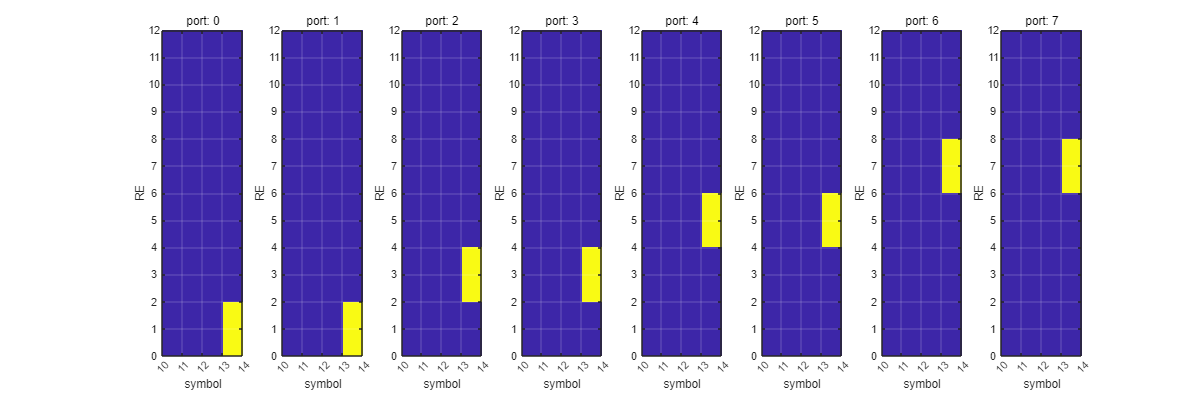

fig = figure;
fig.Position = [100 100 1200 400];
for idx = 1:csirs.NumCSIRSPorts
    subplot(1,csirs.NumCSIRSPorts,idx)
    imagesc(abs(carrierGrid(:,:,idx)));
    set(gca, 'XLim', [10.5, 14.5]);
    set(gca, 'XTick', (10:14)+0.5);
    set(gca, 'XTickLabel', (10:14));
    set(gca, 'XGrid', 'on');
    set(gca, 'GridColor', 'white');
    set(gca, 'YLim', [0.5, 12.5]);
    set(gca, 'YTick', (0:12)+0.5);
    set(gca, 'YTickLabel', (0:12));
    set(gca, 'YGrid', 'on');
    set(gca, 'YDir', 'normal');
    xlabel('symbol');
    ylabel('RE');
    title(['port: ',num2str(idx-1)])
end